clc
clear

disp("Initilization Procedure")

Initilization Procedure


model.Parameters

param = control.calculateOperatingPoint(param);

Calculate Operating Point for T_a = 293.150000 [K]


param = model.calculateModel(param);

Calculate bilinear model matrices
Calculate linearisation decoupled
Calculate linearisation coupled
Testing controlability
Testing T_ref


simtime = 10*60;

## Control

% param.ctrl.Ks = control.DesignProcedure1(param,0); 
param.ctrl.Ks = control.DesignProcedure2(param,0,1);

Evaluation of design procedure 2 
Q is positive definite


ans =     0.0013    0.0013    0.0013    0.0014    0.2122    0.2126    0.2138    0.2147    3.3059    3.3735    3.5081    3.5170


Gamma is found to be:


ans = 1

Eigenvalues of the decoupled systems are all negative 


ans =    -4.0059   -0.0311   -0.0000   -4.0442   -0.0312   -0.0000   -4.0059   -0.0311   -0.0000   -4.0058   -0.0311   -0.0000


Eigenvalues of the coupled systems are all negative 


ans =    -4.0442   -4.0059   -4.0059   -4.0058   -0.0311   -0.0312   -0.0311   -0.0311   -0.0000   -0.0000   -0.0000   -0.0000


## Simulate decoupled system

for i=1:4
    x0 = [param.ctrl.T_wOP(i); param.ctrl.T_aOP(i); 0];
    [t,x] = ode45(@(t,x)model.decoupledDynamics(t,x,i,param,200),[0 simtime],x0);
    decoupledResults(i).time = t;
    decoupledResults(i).Tw = x(:,1);
    decoupledResults(i).Ta = x(:,2);
    decoupledResults(i).T = x(:,3);
end

## Simulate coupled system

x0 = [param.ctrl.T_wOP.'; param.ctrl.T_aOP.'; zeros(4,1)];
options = odeset('RelTol',1e-8,'AbsTol',1e-10);
[t,x] = ode45(@(t,x)model.coupledDynamics(t,x,param,200),[0 simtime],x0,options);
coupledResults.time = t;
coupledResults.Tw = x(:,1:4);
coupledResults.Ta = x(:,5:8);
coupledResults.T = x(:,9:12);

## Plot simulation results

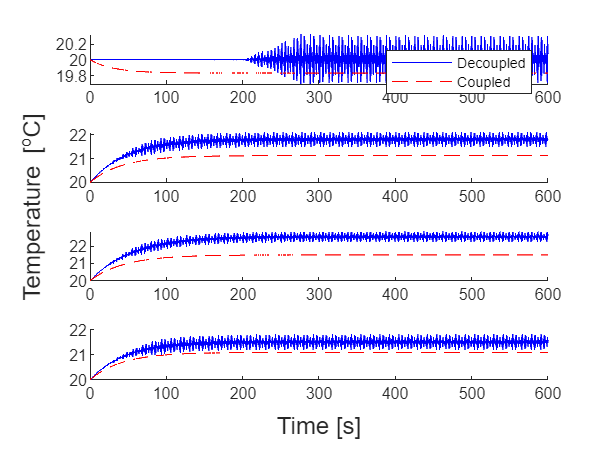

figure()
f = tiledlayout('vertical');
for i=1:4
    nexttile
    hold on
    plot(decoupledResults(i).time,decoupledResults(i).Ta-273.15,'blue')
    plot(coupledResults.time,coupledResults.Ta(:,i)-273.15,['red','--'])
    if i==1
        legend('Decoupled','Coupled',Location='northeast')
    end
    hold off
end
xlabel(f,'Time [s]')
ylabel(f,'Temperature [^{o}C]')
% saveas(gcf,'../Images/Examination_Baseline_PD1','epsc')
% saveas(gcf,'../Images/Examination_Baseline_PD2','epsc')